# MATLAB 101

#### Crash Course for Beginners

`///////////////////////////////////////`

### ASSIGNMENT 02

#### Total Marks : 25

### Problem 1

10 Points

`The code provided below loads the COVID-19 "New cases" dataset for Bangladesh and Afghanistan. Your task is to plot the data  and customize the plot so that it looks similar to this:`

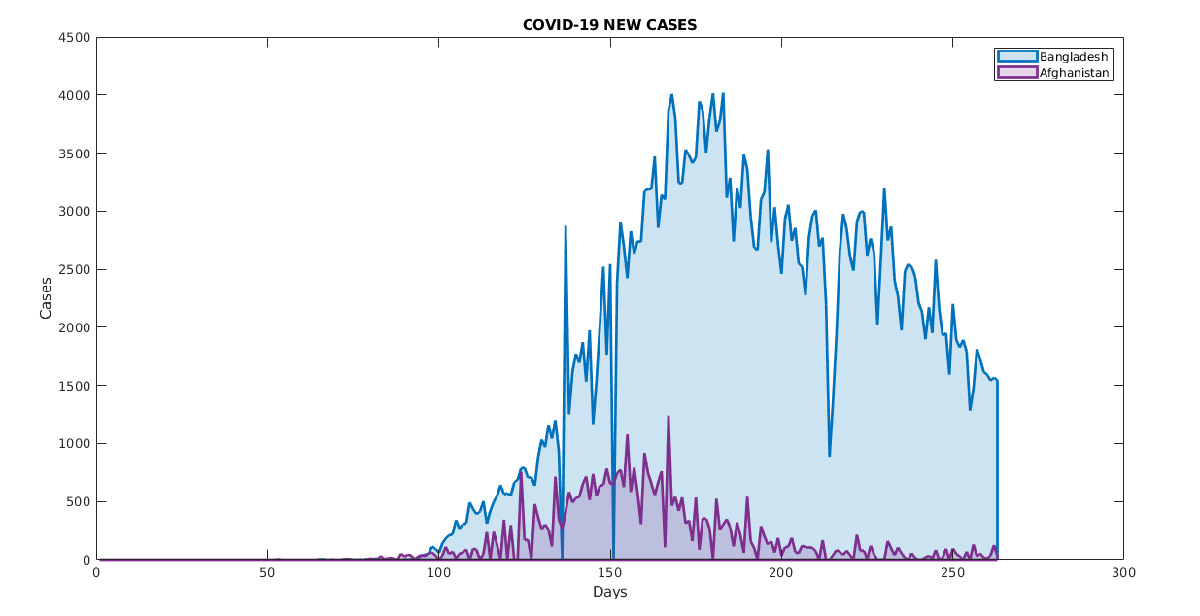

`Hint:`

- `Use area plot. doc: `[`area()`](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.area-properties.html)

- `To customize the plot follow the `[`Area Properties Documentation`](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.area-properties.html)

- **D**`on't forget to add title, labels and legend.`

% This data was taken from : https://covid19.who.int/table

data = readtable('who_covid_19_data.csv');

% FILTERING DATA FOR BD AND AFG
bd = data(strcmp(data.Country, 'Bangladesh'), :);
afg = data(strcmp(data.Country, 'Afghanistan'), :);

% EXTRACTING ONLY NEW CASES DATA
bd_cases = bd.New_cases; % 263x1 Matrix
afg_cases = afg.New_cases; % 263x1 Matrix

% YOUR CODE HERE


### Problem 2

5 Points

`Covert the time domain signal ``'x'`` into a ``frequency domain`` signal using ``Welch`` method. Plot the ``Power Spectral Density (PSD)`` with respect to frequency. Sampling frequency ``Fs = 1000Hz``. `

% LOADING SIGNAL
load signal_x.mat
L = length(x);
Fs = 1000;

% YOUR CODE HERE


### Problem 3

10 Points

`The signal 'x' contains 50Hz and 200Hz components. Design a ``Low-Pass IIR Filter`` to ``remove the 200Hz`` component from the signal using the filter design tool. ``Plot`` the filtered signal in time domain. Try to keep the ``filter order as low as possible`` without distorting the signal.`